clear
clc

# A)

## Checking controllability and observability of the system

Ag=[0 1 0 0 0;-0.1 -0.5 0 0 0;0.5 0 0 0 0;0 0 10 0 0;0.5 1 0 0 0]

Ag =          0    1.0000         0         0         0
   -0.1000   -0.5000         0         0         0
    0.5000         0         0         0         0
         0         0   10.0000         0         0
    0.5000    1.0000         0         0         0


Bg=[0 1 0 0 0]'

Bg =      0
     1
     0
     0
     0


Cg=[0 0 0 1 0]

Cg =      0     0     0     1     0


Dg=0

Dg = 0


system_order = length(Ag)

system_order = 5

M = ctrb(Ag, Bg);
rank_of_M = rank(M)

rank_of_M = 4

N = obsv(Ag, Cg);
rank_of_N = rank(N)

rank_of_N = 4

### The uncontrollable state indicates that M and N does not have full rank of system_order therefore the system is not controllable and observable

# B) 

## Developing a controllable state variable model

[NUM,DEN] = ss2tf(Ag,Bg,Cg,Dg)

NUM =          0         0         0         0    5.0000         0


DEN =     1.0000    0.5000    0.1000         0         0         0


After canceling common factor z

NUM=[0 0 0 0 5];
DEN=[1 0.5 0.1 0 0];
[Ag, Bg, Cg, Dg] = tf2ss(NUM, DEN)

Ag =    -0.5000   -0.1000         0         0
    1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000         0


Bg =      1
     0
     0
     0


Cg =      0     0     0     5


Dg = 0

# C)

Checking controllability and observability

system_order = length(Ag)

system_order = 4

M = ctrb(Ag, Bg);
rank_of_M = rank(M)

rank_of_M = 4

N = obsv(Ag, Cg);
rank_of_N = rank(N)

rank_of_N = 4

The system is controllable and observable because the M and N matrices have the same rank as the system.

# D)

sys=tf(NUM,DEN)

sys =
 
             5
  -----------------------
  s^4 + 0.5 s^3 + 0.1 s^2
 
Continuous-time transfer function.



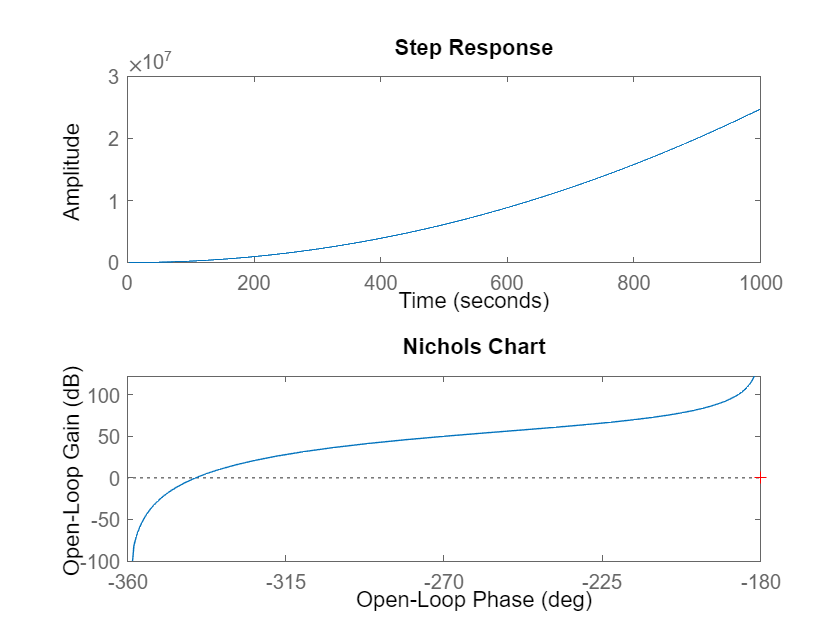

subplot(211)
step(sys)
subplot(212)
nichols(sys)

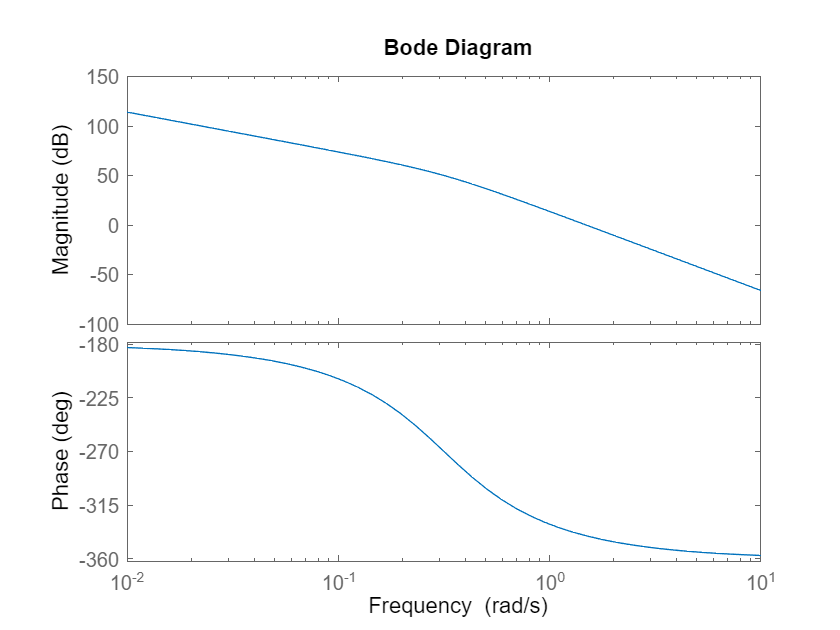

figure
bode(sys)

System is unstable

Designing a state variable feedback controller to stabilize the system

[A,B,C,D] = tf2ss(NUM,DEN)

A =    -0.5000   -0.1000         0         0
    1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000         0


B =      1
     0
     0
     0


C =      0     0     0     5


D = 0

New desired poles for a stable system

new_desired_poles = [-0.25+0.25i -0.25-0.25i -0.5+0.5i -0.5-0.5i];
K = acker(A, B, new_desired_poles)

K =     1.0000    1.0250    0.3750    0.0625


[num2,den2] = ss2tf(A - B * K,B,C,D);
H = tf(num2,den2)

H =
 
                       5
  --------------------------------------------
  s^4 + 1.5 s^3 + 1.125 s^2 + 0.375 s + 0.0625
 
Continuous-time transfer function.



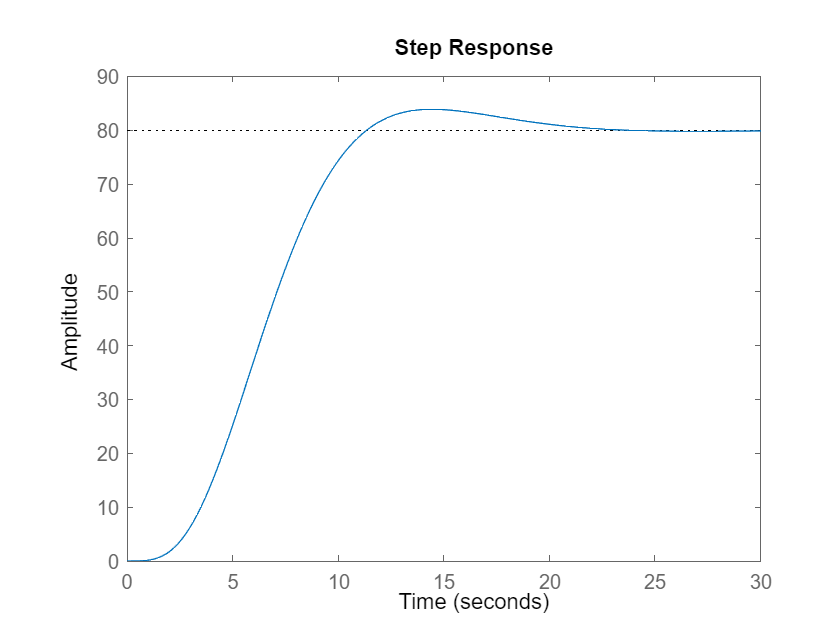

step(H);

System has been stabilized using Ackermann's formula

The original system of 5th order was uncontrollable, unobservable and unstable. After pole-zero cancelation the system became observable and controllable yet unstable. The introduction of a controller rendered the system stable.

The number of state variables i.e. the rank of A matrix must be the same as the controllability matrix for the system to be controllable.